Ref: [https://cran.r-project.org/web/packages/ape/vignettes/MoranI.pdf](https://cran.r-project.org/web/packages/ape/vignettes/MoranI.pdf)

Copied from the above URL:

Moran’s Autocorrelation Coefficient in Comparative Methods Emmanuel Paradis October 4, 2017 

This document clarifies the use of Moran’s autocorrelation coefficient to quantify whether the distribution of a trait among a set of species is affected or not by their phylogenetic relationships.  

**1 Theoretical Background **

Moran’s autocorrelation coefficient (often denoted as I) is an extension of Pearson product-moment correlation coefficient to a univariate series [2, 5]. Recall that Pearson’s correlation (denoted as ρ) between two variables $x$ and $y$ both of length $n$ is: 


$$
ρ = \frac{\sum\limits_{i=1}^n (x_i − \overline{x})(y_i − \overline{y})}{\Big[\sum\limits_{i=1}^n(x_i − \overline{x})^2 \sum\limits_{i=1}^n (y_i − \overline{y})^2\Big]^{1/2}}
$$


where $\overline{x}$ and $\overline{y}$ are the sample means of both variables. ρ measures whether, on average, $x_i$and $y_i$are associated. For a single variable, say $x$, $I$ will measure whether $x_i$and $x_j$ , with $i\not=j$, are associated. Note that with ρ, $x_i$and $x_j$are not associated since the pairs ($x_i$,$y_i$) are assumed to be independent of each other. 

In the study of spatial patterns and processes, we may logically expect that close observations are more likely to be similar than those far apart. It is usual to associate a *weight* to each pair ($x_i$,$x_j$) which quantifies this [3]. In its simplest form, these weights will take values 1 for close neighbours, and 0 otherwise. We also set $w_{ii}=0$. These weights are sometimes referred to as a *neighbouring function*. 

$I$’s formula is: 


$$I = \frac{n}{S_0} \frac{\sum_{i=1}^n \sum_{j=1}^n w_{ij} (x_i − \overline{x})(x_j − \overline{x}) }{\sum_{i=1}^n (x_i − \overline{x})^2}$$


where $w_{ij}$ is the weight between observation $i$ and $j$, and $S_0$ is the sum of all $w_{ij}$’s:


$$S_0 = \sum_{i=1}^n \sum_{j=1}^n w_{ij}$$


Quite not so intuitively, the expected value of $I$ under the null hypothesis of no autocorrelation is not equal to zero but given by $I_0 = −1/(n − 1)$. The expected variance of $I_0$ is also known, and so we can make a test of the null hypothesis. If the observed value of $I$ (denoted $\hat{I}$) is significantly greater than $I_0$, then values of $x$ are positively autocorrelated, whereas if $\hat{I} < I_0$, this will indicate negative autocorrelation. This allows us to design one- or two-tailed tests in the standard way.

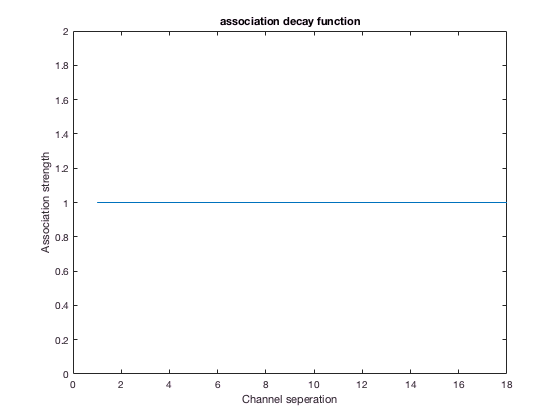

%x = [0,0.6,0.7,0.8,0.4,0.1,0.2,0.5,0.6,0.7,0.8,0.1,0.1,0.05,0.9,0.8,0.7,0.05];
% x = repmat([0 1],1,9); % alternate black white MoransI = -1
x = [zeros(1,9) ones(1,9)]; % perfectly stacked black block over white block: MoranI =+1
n = length(x);
% Neighbor function: How does the association of neighboring points decay?
% assume some exponential
neighborFx = @(lam,v) exp(-(v.*lam));
lambda = 0.2;
neighborDecay = neighborFx(0:n-1,lambda); % 
neighborDecay = [1 1 zeros(1,n-2)]; % for alternating black white
neighborDecay = ones(1,n); %
figure; plot(neighborDecay);title('association decay function');xlabel('Channel seperation'); ylabel('Association strength');

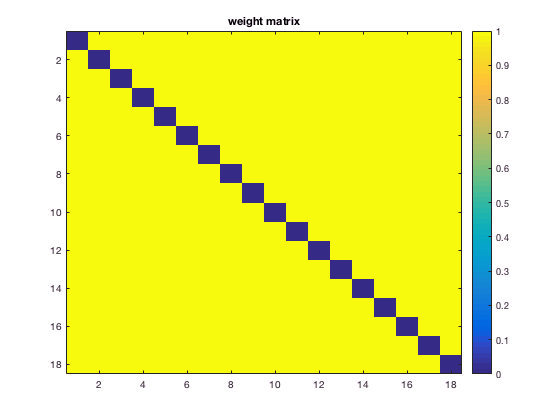

% create weight matrix
w = zeros(n,n); 
for ii=1:n 
    fill = neighborDecay(1:end-ii+1); 
    w(ii,ii:end) = fill; 
    w(ii:end,ii) = fill;
    %set w(i,i) = 0
    w(ii,ii) = 0;
end
figure;imagesc(w);title('weight matrix');colorbar

s0 = sum(w(:)); % sum of weights
xminusxbar = x - nanmean(x(:));
denom = sum(xminusxbar.^2);
numer = 0;
for ii = 1: n
    % since w(i,j) where i=j is already set to 0 
    % the term w(i,i) * (xi-xbar)(xi - xbar) will be zero
    numer = numer + sum(w(ii,:).*(xminusxbar(ii).* xminusxbar)); 
end
I = (n/s0)*numer/denom;
I'

ans =        -0.0588235294117647

**Test Matrices:**

From**: **[https://cran.r-project.org/web/packages/ape/vignettes/MoranI.pdf](https://cran.r-project.org/web/packages/ape/vignettes/MoranI.pdf)

$observed [1] -0.07312179 

$expected [1] -0.25 

$sd [1] 0.08910814 

$p.value [1] 0.04714628

body = [4.09434, 3.61092, 2.37024, 2.02815, -1.46968];
%longevity = [4.74493, 3.3322, 3.3673, 2.89037, 2.30259];
weights=[
 Inf 2.3809524 1.0204082 0.8064516 0.5
 2.3809524 Inf 1.0204082 0.8064516 0.5
 1.0204082 1.0204082 Inf 0.8064516 0.5
 0.8064516 0.8064516 0.8064516 Inf 0.5
 0.5000000 0.5000000 0.5000000 0.5000000 Inf
 ];
weights(isinf(weights)) = 0;


From: [https://stats.idre.ucla.edu/r/faq/how-can-i-calculate-morans-i-in-r/](https://stats.idre.ucla.edu/r/faq/how-can-i-calculate-morans-i-in-r/)

Moran.I(ozone$Av8top, ozone.dists.inv)

$observed [1] 0.2265501

$expected [1] -0.03225806

$sd [1] 0.03431138

$p.value [1] 4.596323e-14

ozone = webread('https://stats.idre.ucla.edu/stat/r/faq/ozone.csv');
% weight matrix
ozoneDist = dist([ozone.Lon,ozone.Lat]');
ozoneDistInv = 1./ozoneDist;
for i=1:size(ozoneDistInv,1)
    ozoneDist(i,i) = 0;
    ozoneDistInv(i,i) = 0;
end
mi = myMoran(ozone.Av8top,ozoneDistInv)


**From spatialclustering (see: **[https://github.com/datarob/spatialfiltering](https://github.com/datarob/spatialfiltering) and [http://www.stat.tugraz.at/AJS/ausg071/071Ferstl.pdf)](http://www.stat.tugraz.at/AJS/ausg071/071Ferstl.pdf))

mi = 

  struct with fields:

                      My: [194×1 double]

                       mi: 0.61850824728805

    moments_exp: -0.00518134715025908

    moments_var: 0.000588700396934195

    moments_skw: 0.435486474063974

    moments_kur: 3.38003412396424

                   z_mi: 25.7052205277426

              prob_nv: 1

                     sad: 1.2877002187839

                  sad_r: 13.0176641249257

                 sad_u: 68.1025417698465

            prob_sad: 1

y = load('y.txt', '-ascii');     % load endogenous variable   
y = y(:,1);
B = load('u.txt', '-ascii');     % load weights matrix
myMoran(y, B)

**Checkerboard (1D)**

cAlter = repmat([0 1],1,4); % alternate black and white
cBlock = [zeros(1,4) ones(1,4)];
cFull = ones(1,8);
cRand = cAlter(randperm(numel(cAlter)));
n = length(cAlter);
w=ones(n,n); w(1:n+1:n*n)=0;
w1=zeros(n,n); w1(2:n+1:n*(n-1))=1; w1(n+1:n+1:n*n)=1;

